# Week 7 Exercise 3

clear
close all

Part (a)

% Constants
g = 9.81;  % Gravity
m = 30;    % Mass
L = 2.5;   % Length of swing from hinge
mu = 7;    % Angular velocity


[Theta,dTheta] = meshgrid(linspace(-pi,pi,101),linspace(-2*sqrt(g/L),2*sqrt(g/L),101));
E = m*g*L*(1-cos(Theta)) + 1/2*m*L^2*dTheta.^2;  % Total Energy

Part (b)

contour(Theta,dTheta,E,20)  % Contour map with E as density with 20 lines
xlabel('\Theta (rads)')
ylabel('\Theta'' (rads/rads)')

Part (c)

hold on
contour(Theta,dTheta,E,[2*m*g*L 2*m*g*L], 'k--')  % Single line for when swing is upside down

Part (d)

[min1, indx1] = min(E);  %  Min of each column
[min2, indx2] = min(min1);  % Overall min
plot(Theta(Theta == min2),dTheta(dTheta == min2),'k*')  % Plot when E is minimum
legend('Part c', 'part b', 'part c')
set(0,'DefaultLegendAutoUpdate','off')

Part (f)

% Initial Conditions
tspan = [0 60];
x0 = [0.99*pi; 0];
u = @(t) 0;
options = odeset('RelTol',1e-3);
[t,x] = ode45(@(t,x) pendulum(x,u(t),m,g,L,mu), tspan, x0, options); % Solving

Part (g)

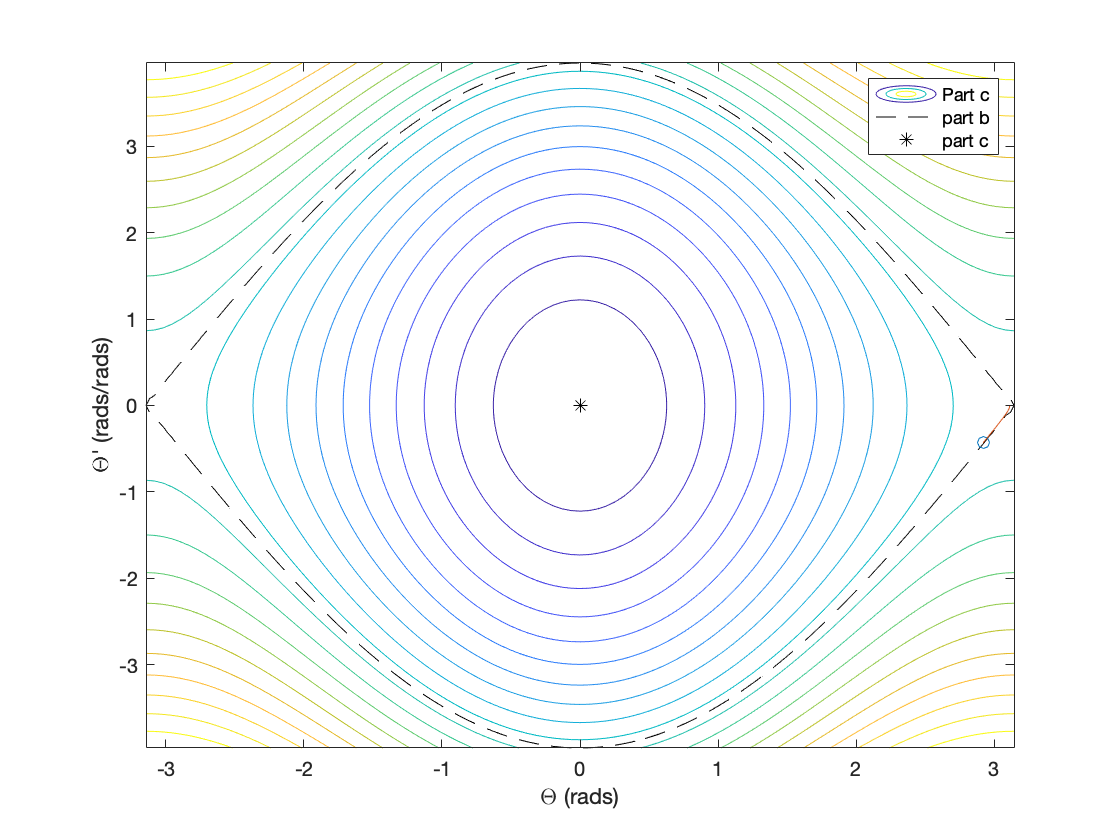

comet(x(:,1),x(:,2),0.99) % Shows trajectory

Part (h)

% Initial Conditions
tspan = [0 60]; 
x0 = x(end,:); % x0 is final value from ode before
u = @(t) m*L^2*sin(sqrt(g/L)*t);
options = odeset('RelTol',1e-3);
[t,x] = ode45(@(t,x) pendulum(x,u(t),m,g,L,mu), tspan, x0, options); % Solving

Part (e)

function dx = pendulum(x,u,m,g,L,mu) % Function to model pendulum
    dx = [x(2)                                      % Theta
          -g/L*sin(x(1)) - mu/m*norm(x(2))*x(2)+u]; % Theta'
end